clear all;

# Generalized Inverse Problem for parameters estimation 

### Initial Problem


$$\partial_t \Psi - \nabla.(D \nabla  \Psi) = G( \Psi, \alpha)+q$$



$$d = M( \Psi)+ \epsilon$$


### Generalized inverse resolution


$$ \partial_t \Psi- \nabla.(D \nabla \Psi) = G( \Psi, \alpha)+<C_q ,\bar\lambda>$$



$$ \Psi(t_0) =  \Phi_0+<C_a, \bar \lambda(t_0)>$$



$$D \nabla \Psi \cdot \vec n=0$$



$$ \partial_t   \bar\lambda- \nabla \cdot(D \nabla \bar \lambda) = - \partial_ \Psi G^T \cdot \bar \lambda - M^T( \delta)W_ \epsilon(d-M( \Psi))$$



$$ \bar \lambda(t_k)=0$$



$$D \nabla \bar \lambda \cdot \vec n=0$$



$$ \alpha =  \alpha_0+C_ \alpha \int_{t_0}^{t_k} \partial_ \alpha G^T \cdot \bar \lambda dt$$


## Resolution

#### Parameters

global t0 tf delta_t N P x h diff_u diff_c;
t0=0e0; tf=7e0; delta_t=1e-2;   N=100;  h=1/(N-1);  P = round((tf-t0)/delta_t+1);
x = linspace(0,1,N)';
diff_u=1e-4; diff_c = 1e-3;

#### Initial condition

a = 1/2;b = 7/10;c = (a+b)/2;
u_0 = zeros(N,1);
c_0 = zeros(N,1);
for i=1:N
    if (abs(x(i)-c)<(b-a)/2)
        y = (x(i)-c)/((b-a)/2);
        u_0(i) = exp(1-1/(1-y^2));
    end
    c_0(i) = 0.5*u_0(i);%1e0-0.5*u_0(i);
end 
L1_N = zeros(N,1);
L2_N = zeros(N,1);
Coefs_0 = log([0.1;0.05;0.0391;0.06;0.1]);
Coefs = Coefs_0;

#### Measurements

Coefs_exact = log([0.2,0.1,0.1,0.03,0.08]);
Measures = measurements(u_0,c_0,Coefs_exact);

#### Covariances matrix and their inverse

C_eps = sparse(diag(h*delta_t*1e2*ones(2*N,1))); %Covariance Matrix of $C_epsilon$
W_eps = inv(C_eps);
C_alpha = sparse(diag((5e0)^2*ones(5,1)));%sparse(diag([2e0,2e0,6e-1,3e-1,2e-0]));
W_alpha = inv(C_alpha);
C_a = sparse(diag(1e0*h*ones(2*N,1)));
W_a = inv(C_a);

####  Resolution of the equation in $\Psi$

index = 1;
Psi1 = zeros(N,P);Psi2 = zeros(N,P);
u_prev = u_0;
c_prev = c_0;
Psi1(:,1) = u_0;Psi2(:,1) = c_0;
CrossProduct = zeros(N,1);
while (index*delta_t<=tf)
    u_t = calc_Psi_1(Coefs, CrossProduct,u_prev);
    c_t = calc_Psi_2(Coefs, CrossProduct,c_prev,u_t);
    Psi1(:,index+1)=u_t;
    Psi2(:,index+1)=c_t;
    u_prev = u_t;
    c_prev = c_t;
    index = index + 1;
end

#### Resolution of the equation in $\bar \lambda$

index = P-1;
Lambda1 = zeros(N,P);Lambda2 = zeros(N,P);
L1_next = L1_N; L2_next = L2_N;
Lambda1(:,P) = L1_N;Lambda2(:,P) = L2_N;
Corr2 = zeros(N,1);
while(index*delta_t>=t0)
    if (mod(index+1,10)==0)
        Corr = W_eps*(Measures(:,index+1)-M(Psi1(:,index+1),Psi2(:,index+1)));
        Corr1 = Corr(1:N,1);
        Corr2 = Corr(N+1:2*N,1);
    else
        Corr1 = zeros(N,1);
        Corr2 = zeros(N,1);
    end
    L2_t = calc_lambda_2(Coefs, Psi1(:,index+1), L2_next, Corr2);
    L1_t = calc_lambda_1(Coefs, Psi1(:,index+1), Psi2(:,index+1),L1_next, L2_t, Corr1);
    Lambda1(:,index+1) = L1_t;
    Lambda2(:,index+1) = L2_t;
    L1_next = L1_t; L2_next = L2_t;
    index = index - 1;
end

#### Calibration of parameters

%Int_approx = calc_int_param(Lambda1, Lambda2, Psi1, Psi2, Coefs);
%Coefs = Coefs_0 + C_alpha*Int_approx;
%options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
%lb=Coefs_0-1;ub=Coefs_0+1;
%fun = @(x) 1e4*norm(calc_int_param(Lambda1, Lambda2, Psi1, Psi2, x),2);
%[Coefs,fval,exitflag,output] = fmincon(fun,Coefs_0,[],[],[],[],lb,ub,[],options);
% Coefs_prev = Coefs;
% cond2 = 1e0;counter_here = 0;
% while (cond2>=1e-6)  %Coefs = Coefs_0 + C_alpha*Int_approx;
%     Int_approx = calc_int_param(Lambda1, Lambda2, Psi1, Psi2, Coefs_prev);
%     Coefs_next = Coefs_prev - 0.1*(Coefs_prev-Coefs_0 -C_alpha*Int_approx);
%     cond2 = norm(Coefs_next-Coefs_prev)/norm(Coefs_prev);
%     Coefs_prev = Coefs_next;
%     counter_here = counter_here + 1 ;
% end
% Coefs = Coefs_next;
%disp(exp(Coefs));

### Calculs des erreurs

#### Erreur de l'équation dynamique $e_1 = \int\int\int\int(\partial_t \Psi - \nabla.(D \nabla  \Psi) - G( \Psi, \alpha))^T\cdot W_q \cdot (\partial_t \Psi - \nabla.(D \nabla  \Psi) - G( \Psi, \alpha))$

#### 
$$= \int \int (\partial_t \Psi - \nabla.(D \nabla  \Psi) - G( \Psi, \alpha))^T\cdot \bar\lambda$$


Vect = Int_model_error(Lambda1,Lambda2); % donne le premier terme de l'erreur
Big_lambda = [Lambda1;Lambda2]; % Lambda sous forme de vecteur
e1 = h*delta_t*trace(Vect'*Big_lambda);
disp('e1 = ');disp(e1);

e1 = 
   1.9619e+03



#### Erreur sur la condition initiale $e_2 = \int\int (\Psi(t_0)-\Phi_0)^T\cdot W_a \cdot (\Psi(t_0)-\Phi_0)$

Err_cond_ini = C_a*[Lambda1(:,1);Lambda2(:,1)]; % Premier terme de l'erreur e2
e2 = h*Err_cond_ini'*W_a*Err_cond_ini;
disp('e2 = ');disp(e2);

e2 = 
    0.0352



#### Erreur sur les coefficients $e_3 = (\alpha -\alpha_0)^T W_\alpha (\alpha - \alpha_0)$

Err_alpha = Coefs - Coefs_0;
e3 = Err_alpha'*W_alpha*Err_alpha;
disp('e3 = ');disp(e3);

e3 = 
     0



#### Erreur sur les mesures $e_4 = (d-M(\Psi))^T W_\epsilon (d-M(\Psi))$

Err_measure = Measures - M(Psi1,Psi2);
e4 = trace(Err_measure'*W_eps*Err_measure);
disp('e4 = ');disp(e4);

e4 = 
   2.2057e+04



#### Plots 

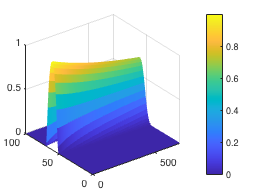

figure;mesh(Psi1);colorbar;

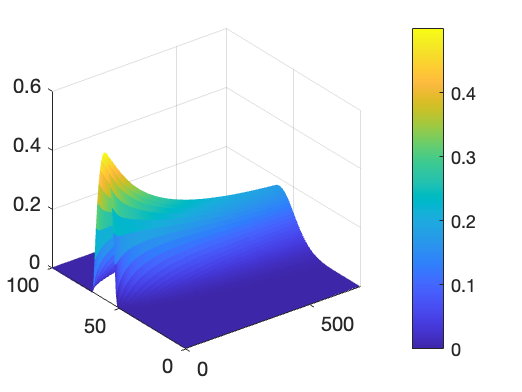

figure;mesh(Psi2);colorbar;

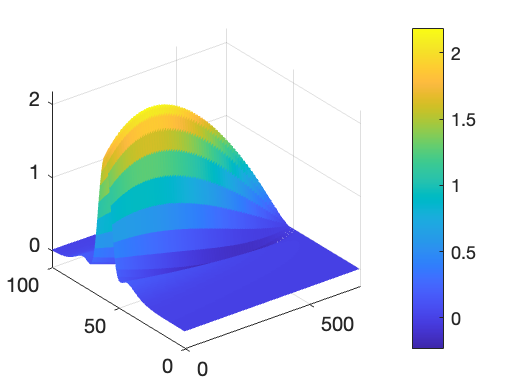

figure;mesh(Lambda1);colorbar;

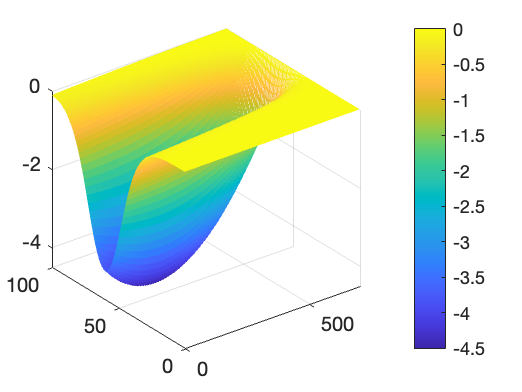

figure;mesh(Lambda2);colorbar;

### Iteration in the functions

iter = 1; itermax = 20;
Coefs_all = zeros(5,itermax+1);
Coefs_all(:,1) = Coefs;
cond = false;
%bar = waitbar(0,'Lets get started');
while (iter<=itermax && ~cond)
    %waitbar(iter/itermax,bar,'Progression');
    %Psi
    index = 1;
    Psi1 = zeros(N,P);Psi2 = zeros(N,P);
    Err_cond_ini = C_a*[Lambda1(:,1);Lambda2(:,1)];
    u_prev = u_0 + (Err_cond_ini(1:N,1)); % à compléter
    c_prev = c_0 + (Err_cond_ini(N+1:2*N,1)); % à compléter
    Psi1(:,1) = u_prev;Psi2(:,1) = c_prev;
    CrossProduct = Int_model_error(Lambda1,Lambda2);
    while (index*delta_t<=tf)
        u_t = calc_Psi_1(Coefs, CrossProduct(1:N,index),u_prev);
        c_t = calc_Psi_2(Coefs, CrossProduct(N+1:2*N,index),c_prev,u_t);
        Psi1(:,index+1)=u_t;
        Psi2(:,index+1)=c_t;
        u_prev = u_t;
        c_prev = c_t;
        index = index + 1;
    end
    
    %Lambda
    index = P-1;
    Lambda1 = zeros(N,P);Lambda2 = zeros(N,P);
    L1_next = L1_N; L2_next = L2_N;
    Lambda1(:,P) = L1_N;Lambda2(:,P) = L2_N;
    Corr2 = zeros(N,1);
    while(index*delta_t>=t0)
        if (mod(index+1,10)==0)
            Corr = W_eps*(Measures(:,index+1)-M(Psi1(:,index+1),Psi2(:,index+1)));
            Corr1 = Corr(1:N,1);
            Corr2 = Corr(N+1:2*N,1);
        else
            Corr1 = zeros(N,1);
            Corr2 = zeros(N,1);
        end
        L2_t = calc_lambda_2(Coefs, Psi1(:,index+1), L2_next, Corr2);
        L1_t = calc_lambda_1(Coefs, Psi1(:,index+1), Psi2(:,index+1),L1_next, L2_t, Corr1);
        Lambda1(:,index+1) = L1_t;
        Lambda2(:,index+1) = L2_t;
        L1_next = L1_t; L2_next = L2_t;
        index = index - 1;
    end
    
    %Alpha
%     Coefs_prev = Coefs;
%     cond2 = 1e0;counter_here = 0;
%     while (cond2>=1e-6)  %Coefs = Coefs_0 + C_alpha*Int_approx;
%         Int_approx = calc_int_param(Lambda1, Lambda2, Psi1, Psi2, Coefs_prev);
%         Coefs_next = Coefs_prev - 0.01*(Coefs_prev-Coefs_0 -C_alpha*Int_approx);
%         cond2 = norm(Coefs_next-Coefs_prev)/norm(Coefs_prev);
%         Coefs_prev = Coefs_next;
%         counter_here = counter_here + 1 ;
%     end
%     Coefs = Coefs_next;
%     disp(counter_here);
   % lb=Coefs_0-1.5;ub=Coefs_0+1.5;
   % fun = @(x) 1e4*norm(calc_int_param(Lambda1, Lambda2, Psi1, Psi2, x),2);
   % [Coefs,fval,exitflag,output] = fmincon(fun,Coefs,[],[],[],[],lb,ub);
    %Coefs = Coefs_all(:,iter) -0.01*(Coefs_all(:,iter)-Coefs_0 -C_alpha*Int_approx);
    
    iter = iter+1;
   % Coefs_all(:,iter) = Coefs;
    
    Vect = Int_model_error(Lambda1,Lambda2); % donne le premier terme de l'erreur
    Big_lambda = [Lambda1;Lambda2]; % Lambda sous forme de vecteur
    e1 = h*delta_t*trace(Vect'*Big_lambda);

    Err_cond_ini = C_a*[Lambda1(:,1);Lambda2(:,1)]; % Premier terme de l'erreur e2
    e2 = h*Err_cond_ini'*W_a*Err_cond_ini;

    Err_measure = Measures - M(Psi1,Psi2);
    e4 = trace(Err_measure'*W_eps*Err_measure);
    

    cond = (e1>=1e-4) && (e2>=1e-4) && (e4>=1e-1);
end
%close(bar);
disp('e1 = ');disp(e1);

e1 = 
   1.4574e+28



disp('e2 = ');disp(e2);

e2 = 
   1.4908e+21



disp('e4 = ');disp(e4);

e4 = 
   5.4459e+13



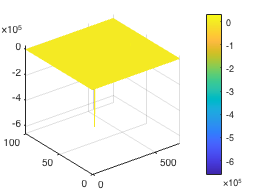

figure;mesh(Psi1);colorbar;

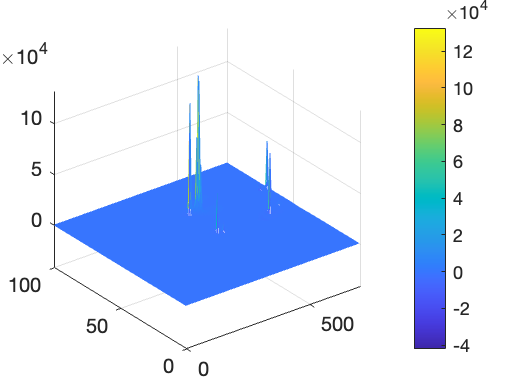

figure;mesh(Psi2);colorbar;

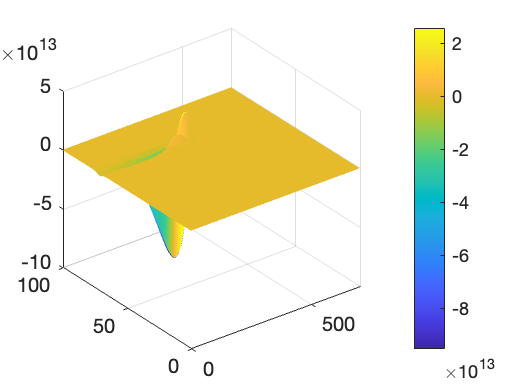

figure;mesh(Lambda1);colorbar;

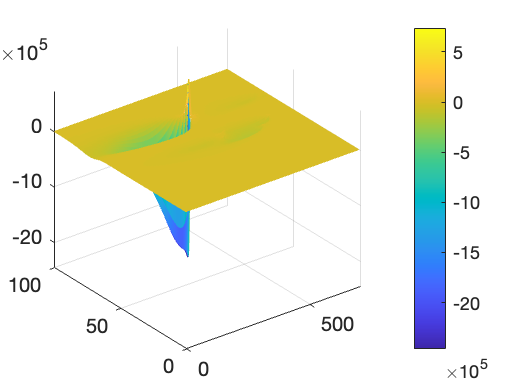

figure;mesh(Lambda2);colorbar;

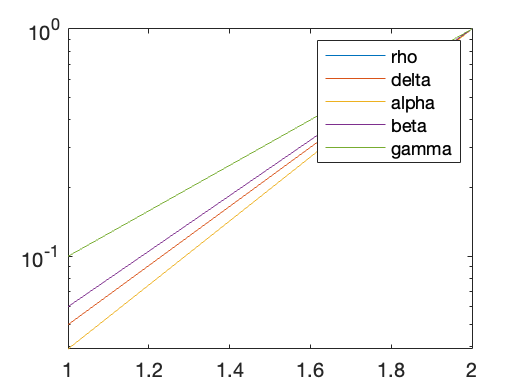

figure;semilogy(exp(Coefs_all(:,1:iter)'));legend('rho','delta','alpha','beta','gamma');